## Parámetros

% Eslabón 1
m1 = 0.239 %0.121 %kg

m1 = 0.2390

l1 = 0.190 %m

l1 = 0.1900

lc1 = 0.140  %0.095 %m

lc1 = 0.1400

I1 =  9.2E-4  %Nms^2 4.1E-4

I1 = 9.2000e-04


% Eslabón 2
m2 = 0.134 %kg 

m2 = 0.1340

l2 = 0.180 %m

l2 = 0.1800

lc2 = 0.098 %m

lc2 = 0.0980

I2 = 3.6E-4 %Nms^2

I2 = 3.6000e-04


g = 9.81 %m/s^2

g = 9.8100


syms q1(t) q2(t) t theta

## Cinematica directa y diferencial

%xy2 = @(q1,q2) [l1*cos(q1)+lc2*cos(q1+q2); l1*sin(q1)+lc2*sin(q1+q2)];
%xy2(0,pi/2)
%v1 = @(q1,vq1) [-lc1*sin(q1); lc1*cos(q1)].*vq1;
%v1(pi/2,1)
%v2 = @(q1,q2,vq1,vq2) [-l1*sin(q1)-lc2*sin(q1+q2) -lc2*sin(q1+q2); l1*cos(q1)+lc2*cos(q1+q2) lc2*cos(q1+q2)]*[vq1;vq2];
%v2(0,0,1,1)
xy1 = [lc1*cos(q1); lc1*sin(q1)]

$$xy1(t) = \left(\begin{array}{c} \frac{7\,\cos\left(q_{1}\left(t\right)\right)}{50}\\ \frac{7\,\sin\left(q_{1}\left(t\right)\right)}{50} \end{array}\right)$$

xy2 = [l1*cos(q1)+lc2*cos(q1+q2); l1*sin(q1)+lc2*sin(q1+q2)]

$$xy2(t) = \left(\begin{array}{c} \frac{19\,\cos\left(q_{1}\left(t\right)\right)}{100}+\frac{49\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)}{500}\\ \frac{19\,\sin\left(q_{1}\left(t\right)\right)}{100}+\frac{49\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)}{500} \end{array}\right)$$

cdE = [l1*cos(q1)+l2*cos(q1+q2); l1*sin(q1)+l2*sin(q1+q2)]

$$cdE(t) = \left(\begin{array}{c} \frac{19\,\cos\left(q_{1}\left(t\right)\right)}{100}+\frac{9\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)}{50}\\ \frac{19\,\sin\left(q_{1}\left(t\right)\right)}{100}+\frac{9\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)}{50} \end{array}\right)$$

v1 = diff(xy1,t)

$$v1(t) = \left(\begin{array}{c} -\frac{7\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{50}\\ \frac{7\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{50} \end{array}\right)$$

v2 = diff(xy2,t)

$$v2(t) = \begin{array}{l} \left(\begin{array}{c} -\frac{19\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{100}-\frac{49\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\sigma_{1}}{500}\\ \frac{19\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{100}+\frac{49\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\sigma_{1}}{500} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right) \end{array}$$

## Cinemática Inversa

ci_q2 = @(x,y) acos((x.^2+y.^2-l1^2-l2^2)/(2*l1*l2))

ci_q2 = function_handle with value:
    @(x,y)acos((x.^2+y.^2-l1^2-l2^2)/(2*l1*l2))


ci_q1 = @(x,y,q2) atan2(y,x) - atan2(l2.*sin(q2),l1+l2.*cos(q2))

ci_q1 = function_handle with value:
    @(x,y,q2)atan2(y,x)-atan2(l2.*sin(q2),l1+l2.*cos(q2))


## Energía Cinética

K = 1/2*(m1*transpose(v1)*v1 + I1*diff(q1,t)^2 + m2*transpose(v2)*v2 + I2*(diff(q1,t)+diff(q2,t))^2)

$$K(t) = \begin{array}{l} \frac{23\,\sigma_{2}}{50000}+\frac{11711\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{5000000}+\frac{11711\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{5000000}+\frac{9\,{\sigma_{1}}^{2}}{50000}+\frac{\left(\frac{19\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{100}+\frac{49\,\cos\left(\sigma_{3}\right)\,\sigma_{1}}{500}\right)\,\left(\frac{1273\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{50000}+\frac{3283\,\cos\left(\sigma_{3}\right)\,\sigma_{1}}{250000}\right)}{2}+\frac{\left(\frac{19\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{100}+\frac{49\,\sin\left(\sigma_{3}\right)\,\sigma_{1}}{500}\right)\,\left(\frac{1273\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{50000}+\frac{3283\,\sin\left(\sigma_{3}\right)\,\sigma_{1}}{250000}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$

## Energía Potencial

U = m1*g*lc1*sin(q1) + m2*g*(l1*sin(q1)+lc2*sin(q1+q2))

$$U(t) = \frac{203367500260797597207\,\sin\left(q_{1}\left(t\right)\right)}{351843720888320000000}+\frac{3220623\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)}{25000000}$$

## Lagrangiano

L =  K-U

$$L(t) = \begin{array}{l} \frac{23\,\sigma_{2}}{50000}-\frac{3220623\,\sin\left(\sigma_{3}\right)}{25000000}-\frac{203367500260797597207\,\sin\left(q_{1}\left(t\right)\right)}{351843720888320000000}+\frac{11711\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{5000000}+\frac{11711\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{5000000}+\frac{9\,{\sigma_{1}}^{2}}{50000}+\frac{\left(\frac{19\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{100}+\frac{49\,\cos\left(\sigma_{3}\right)\,\sigma_{1}}{500}\right)\,\left(\frac{1273\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{50000}+\frac{3283\,\cos\left(\sigma_{3}\right)\,\sigma_{1}}{250000}\right)}{2}+\frac{\left(\frac{19\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{100}+\frac{49\,\sin\left(\sigma_{3}\right)\,\sigma_{1}}{500}\right)\,\left(\frac{1273\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{50000}+\frac{3283\,\sin\left(\sigma_{3}\right)\,\sigma_{1}}{250000}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$

### Ecuacion de movimiento Euler-Lagrange

vq1 = diff(q1,t)

$$vq1(t) = \frac{\partial }{\partial t}q_{1}\left(t\right)$$

vq2 = diff(q2,t)

$$vq2(t) = \frac{\partial }{\partial t}q_{2}\left(t\right)$$

C1 = diff(L,vq1)

$$C1(t) = \begin{array}{l} \frac{\left(\frac{19\,\sin\left(q_{1}\left(t\right)\right)}{100}+\frac{49\,\sin\left(\sigma_{2}\right)}{500}\right)\,\left(\frac{1273\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{50000}+\frac{3283\,\sin\left(\sigma_{2}\right)\,\sigma_{1}}{250000}\right)}{2}+\frac{\left(\frac{1273\,\sin\left(q_{1}\left(t\right)\right)}{50000}+\frac{3283\,\sin\left(\sigma_{2}\right)}{250000}\right)\,\left(\frac{19\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{100}+\frac{49\,\sin\left(\sigma_{2}\right)\,\sigma_{1}}{500}\right)}{2}+\frac{4\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{3125}+\frac{9\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{25000}+\frac{11711\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{2500000}+\frac{11711\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{2500000}+\frac{\left(\frac{19\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{100}+\frac{49\,\cos\left(\sigma_{2}\right)\,\sigma_{1}}{500}\right)\,\left(\frac{1273\,\cos\left(q_{1}\left(t\right)\right)}{50000}+\frac{3283\,\cos\left(\sigma_{2}\right)}{250000}\right)}{2}+\frac{\left(\frac{1273\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{50000}+\frac{3283\,\cos\left(\sigma_{2}\right)\,\sigma_{1}}{250000}\right)\,\left(\frac{19\,\cos\left(q_{1}\left(t\right)\right)}{100}+\frac{49\,\cos\left(\sigma_{2}\right)}{500}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$

C2 = diff(L,vq2)

$$C2(t) = \begin{array}{l} \frac{\cos\left(\sigma_{2}\right)\,\left(\frac{19\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{100}+\frac{49\,\cos\left(\sigma_{2}\right)\,\sigma_{1}}{500}\right)\,3283}{500000}+\frac{\cos\left(\sigma_{2}\right)\,\left(\frac{1273\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{50000}+\frac{3283\,\cos\left(\sigma_{2}\right)\,\sigma_{1}}{250000}\right)\,49}{1000}+\frac{\sin\left(\sigma_{2}\right)\,\left(\frac{19\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{100}+\frac{49\,\sin\left(\sigma_{2}\right)\,\sigma_{1}}{500}\right)\,3283}{500000}+\frac{\sin\left(\sigma_{2}\right)\,\left(\frac{1273\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{50000}+\frac{3283\,\sin\left(\sigma_{2}\right)\,\sigma_{1}}{250000}\right)\,49}{1000}+\frac{9\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{25000}+\frac{9\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{25000}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$

C3 = diff(C1,t)

C4 = diff(C2,t)

C5 = diff(L,q1)

$$C5(t) = -\frac{203367500260797597207\,\cos\left(q_{1}\left(t\right)\right)}{351843720888320000000}-\frac{3220623\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)}{25000000}$$

C6 = diff(L,q2)

$$C6(t) = \begin{array}{l} \frac{\cos\left(\sigma_{2}\right)\,\left(\frac{19\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{100}+\frac{49\,\sin\left(\sigma_{2}\right)\,\sigma_{1}}{500}\right)\,\sigma_{1}\,3283}{500000}-\frac{\sin\left(\sigma_{2}\right)\,\left(\frac{19\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{100}+\frac{49\,\cos\left(\sigma_{2}\right)\,\sigma_{1}}{500}\right)\,\sigma_{1}\,3283}{500000}-\frac{\sin\left(\sigma_{2}\right)\,\left(\frac{1273\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{50000}+\frac{3283\,\cos\left(\sigma_{2}\right)\,\sigma_{1}}{250000}\right)\,\sigma_{1}\,49}{1000}-\frac{3220623\,\cos\left(\sigma_{2}\right)}{25000000}+\frac{\cos\left(\sigma_{2}\right)\,\left(\frac{1273\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)}{50000}+\frac{3283\,\sin\left(\sigma_{2}\right)\,\sigma_{1}}{250000}\right)\,\sigma_{1}\,49}{1000}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$


tau = [C3 - C5; C4 - C6]

Test

%q1 = @(t) 0.27*t;
%q2 = @(t) 0;
%t=[0,1];
%q1(t)
%q2(t)
%double(subs(v2))
%double(subs(tau))

Trevor

a = 3.2604;
k = 3;
b = 1;
r = a*k+a*cos(4*theta+b*pi);
x = (r.*cos(theta) + 20)/100;
y = (r.*sin(theta) + 9)/100;

theta = 0:0.1:2*pi;
x = double(subs(x));
y = double(subs(y));

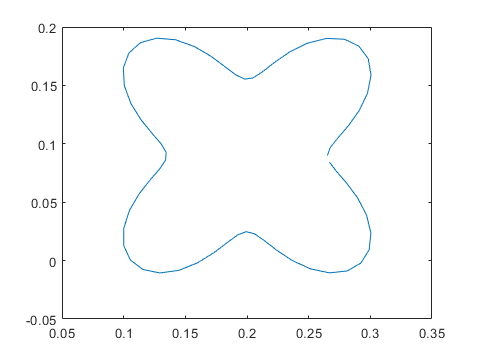

plot(x,y)

t_total = 10

t_total = 10

tdas = 0:t_total/62:t_total

tdas =          0    0.1613    0.3226    0.4839    0.6452    0.8065    0.9677    1.1290    1.2903    1.4516    1.6129    1.7742    1.9355    2.0968    2.2581    2.4194    2.5806    2.7419    2.9032    3.0645    3.2258    3.3871    3.5484    3.7097    3.8710    4.0323    4.1935    4.3548    4.5161    4.6774    4.8387    5.0000    5.1613    5.3226    5.4839    5.6452    5.8065    5.9677    6.1290    6.2903    6.4516    6.6129    6.7742    6.9355    7.0968    7.2581    7.4194    7.5806    7.7419    7.9032


ciq2 = ci_q2(x,y);
q2p = fit(transpose(0:t_total/62:t_total),transpose(ciq2),'sin6')

q2p =      General model Sin6:
     q2p(x) =  
                    a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3) + 
                    a4*sin(b4*x+c4) + a5*sin(b5*x+c5) + a6*sin(b6*x+c6)
     Coefficients (with 95% confidence bounds):
       a1 =       2.501  (-725.4, 730.4)
       b1 =      0.2486  (-36.17, 36.67)
       c1 =      0.5381  (-303.2, 304.2)
       a2 =      0.7134  (-873.6, 875)
       b2 =      0.4311  (-150.2, 151.1)
       c2 =         3.8  (-771.9, 779.5)
       a3 =      0.1799  (-25.17, 25.53)
       b3 =       1.101  (-43.65, 45.86)
       c3 =       2.036  (-236.6, 240.7)
       a4 =      0.1711  (-3.459, 3.801)
       b4 =       1.865  (-19.21, 22.94)
       c4 =        1.96  (-123.6, 127.5)
       a5 =      0.1216  (-5.017, 5.26)
       b5 =       2.436  (-12.9, 17.77)
       c5 =       1.769  (-85.76, 89.3)
       a6 =      0.1329  (-0.7305, 0.9963)
       b6 =       3.081  (1.848, 4.313)
       c6 =       1.278  (-5.588, 8.144)


c2 = coeffvalues(q2p);
q2 = @(t) c2(1)*sin(c2(2)*t+c2(3)) + c2(4)*sin(c2(5)*t+c2(6)) + c2(7)*sin(c2(8)*t+c2(9)) + c2(10)*sin(c2(11)*t+c2(12)) + c2(13)*sin(c2(14)*t+c2(15)) + c2(16)*sin(c2(17)*t+c2(18)) 

q2 = function_handle with value:
    @(t)c2(1)*sin(c2(2)*t+c2(3))+c2(4)*sin(c2(5)*t+c2(6))+c2(7)*sin(c2(8)*t+c2(9))+c2(10)*sin(c2(11)*t+c2(12))+c2(13)*sin(c2(14)*t+c2(15))+c2(16)*sin(c2(17)*t+c2(18))


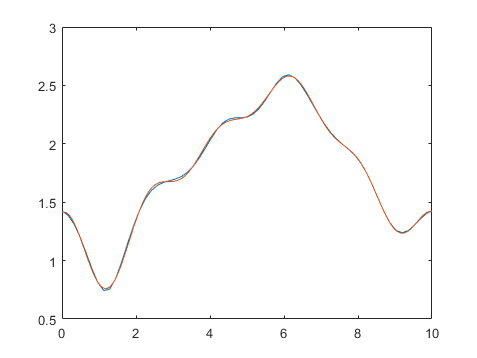

%q2 = @(t) feval(q2p,t)

plot(tdas,ciq2)
hold on
fplot(q2)
xlim([0 10])
hold off


ciq1 = ci_q1(x,y,ciq2);
q1p = fit(transpose(0:t_total/62:t_total),transpose(ciq1),'sin9');
c1 = coeffvalues(q1p);
q1 = @(t) c1(1)*sin(c1(2)*t+c1(3)) + c1(4)*sin(c1(5)*t+c1(6)) + c1(7)*sin(c1(8)*t+c1(9)) + c1(10)*sin(c1(11)*t+c1(12)) + c1(13)*sin(c1(14)*t+c1(15)) + c1(16)*sin(c1(17)*t+c1(18)) + c1(19)*sin(c1(20)*t+c1(21)) + c1(22)*sin(c1(23)*t+c1(24)) + c1(25)*sin(c1(26)*t+c1(27))

q1 = function_handle with value:
    @(t)c1(1)*sin(c1(2)*t+c1(3))+c1(4)*sin(c1(5)*t+c1(6))+c1(7)*sin(c1(8)*t+c1(9))+c1(10)*sin(c1(11)*t+c1(12))+c1(13)*sin(c1(14)*t+c1(15))+c1(16)*sin(c1(17)*t+c1(18))+c1(19)*sin(c1(20)*t+c1(21))+c1(22)*sin(c1(23)*t+c1(24))+c1(25)*sin(c1(26)*t+c1(27))


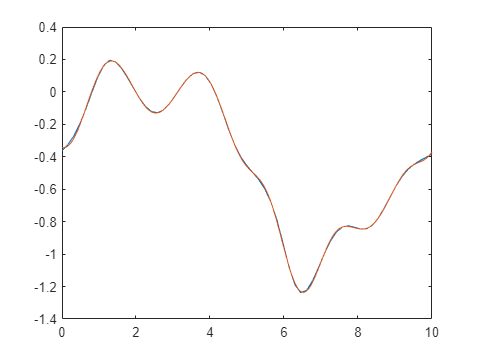

%q1 = @(t) feval(q1p,t)

plot(tdas,ciq1)
hold on
fplot(q1)
xlim([0 10])
hold off


t = 0:t_total/62:t_total

t =          0    0.1613    0.3226    0.4839    0.6452    0.8065    0.9677    1.1290    1.2903    1.4516    1.6129    1.7742    1.9355    2.0968    2.2581    2.4194    2.5806    2.7419    2.9032    3.0645    3.2258    3.3871    3.5484    3.7097    3.8710    4.0323    4.1935    4.3548    4.5161    4.6774    4.8387    5.0000    5.1613    5.3226    5.4839    5.6452    5.8065    5.9677    6.1290    6.2903    6.4516    6.6129    6.7742    6.9355    7.0968    7.2581    7.4194    7.5806    7.7419    7.9032


q2v = double(subs(q2));
q1v = double(subs(q1));
cdEv = double(subs(cdE));
xy2_v = double(subs(xy2));
v1_v = double(subs(v1));
v2_v = double(subs(v2));
tau_v = double(subs(tau));

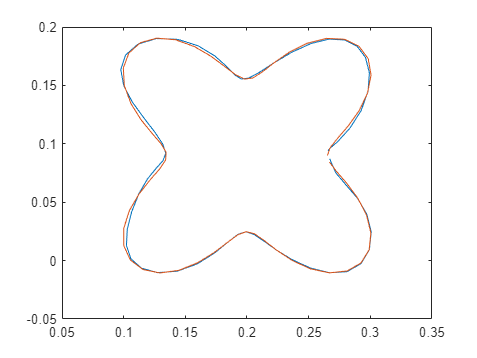

tau_q1 = tau_v(1,:);
tau_q2 = tau_v(2,:);

v2_x = v2_v(1,:);
v2_y = v2_v(2,:);

norm_v2 = sqrt(v2_x.^2+v2_y.^2);


plot(cdEv(1,:),cdEv(2,:))
hold on
plot(x,y)
hold off

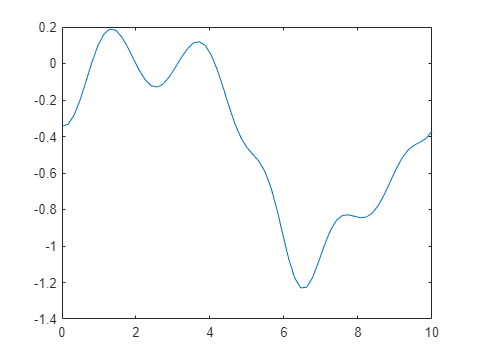


plot(t,q1v);

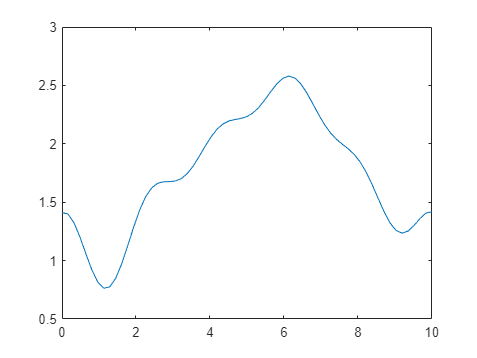

plot(t,q2v);

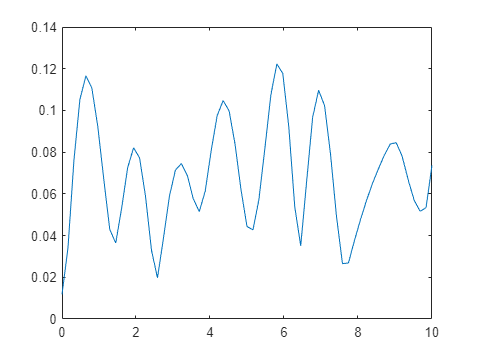


plot(t,norm_v2)

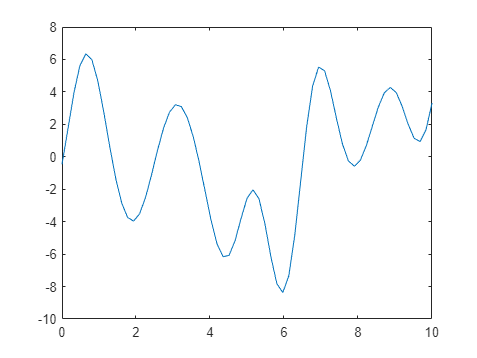


plot(t,double(subs(vq1))*30/pi)

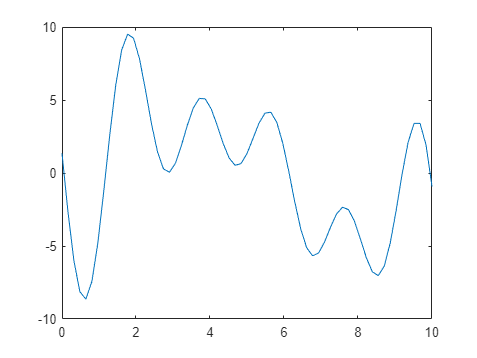

plot(t,double(subs(vq2))*30/pi)

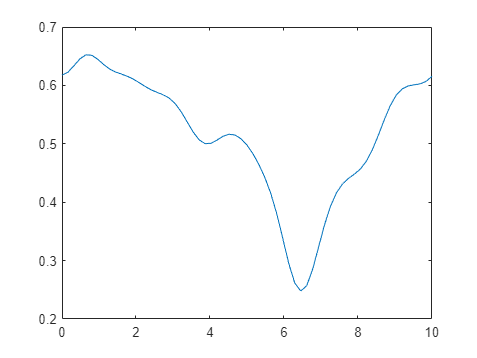


plot(t,tau_q1)

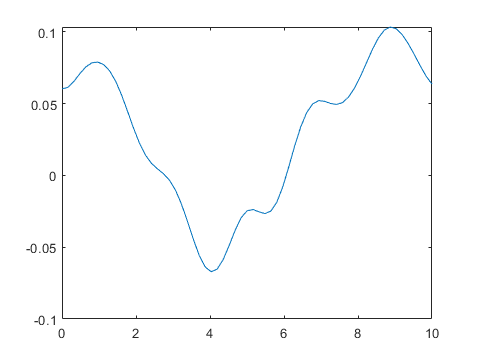

plot(t,tau_q2)


pos1 = [t; q1v]'

pos1 =          0   -0.3433
    0.1613   -0.3330
    0.3226   -0.2847
    0.4839   -0.2029
    0.6452   -0.1003
    0.8065    0.0054
    0.9677    0.0967
    1.1290    0.1601
    1.2903    0.1888
    1.4516    0.1824


pos2 = [t; q2v]'

pos2 =          0    1.4109
    0.1613    1.3994
    0.3226    1.3247
    0.4839    1.2031
    0.6452    1.0590
    0.8065    0.9209
    0.9677    0.8156
    1.1290    0.7637
    1.2903    0.7752
    1.4516    0.8489
